# Introduction to Optimization: Heron's Shortest Path

Simple path planning example to illustrate formulating a problem for optimization.

The approach is similar to what we saw with solving ODEs

- Formulate the problem as an optimization problem (standard mathematical forms)

- Choose an appropriate algorithm (solver)

- Implement (code)

- Verify and validate solution (visualize and error management)

## Find the shortest path

(Adapted from ME3420, S. Kragelund)

Consider two villiages located along a river with the geometry shown below.  

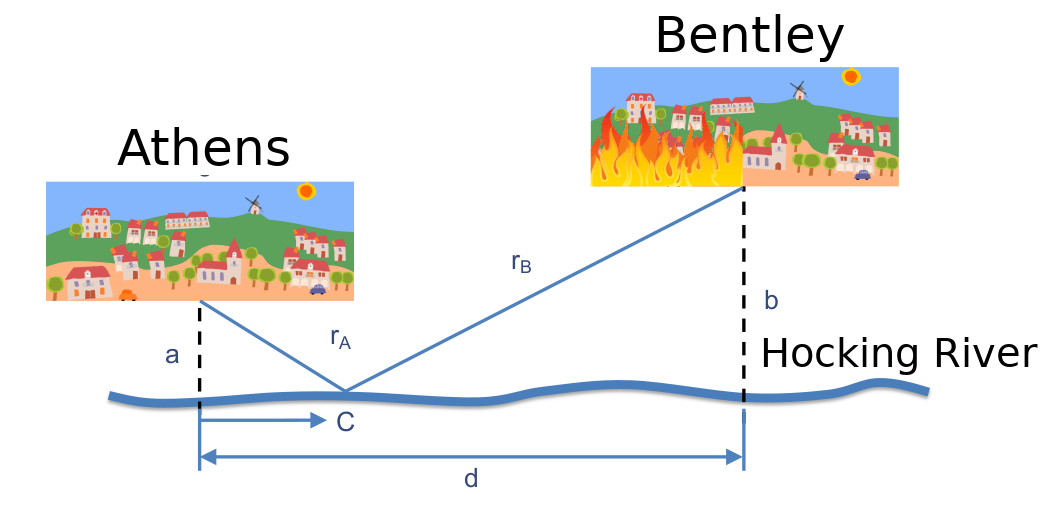

Ther is a tremendous fire in Bently and the residents of Athens wish to help by delivering river water to Bently.   

They want to find the shortest distance from A to B via the river $(r_A + r_B)$ so they can fill their buckets along the way.

**Given **geometry illustrated above and the distances...

- a = 2 km

- b = 3 km

- d = 5 km

**Find the location along the river, C, the minimizes the path **$(r_A + r_B)$**.**

## General Formulation

The example above is a specific case of a generic unconstrained optimization problem which can be expressed as


$$\min_{\mathbf{x} \in \mathbb{R}^n} \; f(\mathbf{x})
$$


where 

- $ \mathbf{x} \in \mathbb{R}^n $ is the decision (design) variable vector.  

- $ f(\mathbf{x}) $ is a scalar-valued objective function.

The job of the solver is to find values for the decision/design parameters that minimize the cost/objective function.

## Approaches

We could find a shortest (or at least a short) path a few ways: 

- exaustive search, 

- calculus (analytical solution) 

- or optimization (numerical).

## Formulate as an optimzation problem

Optimization solvers can provide powerful algorithms for finding the "best" possible solution, but we need to define clearly what we mean by "best".  

In this context we want to find the shortest path.  In terms of optimation, the ***cost function***** or *****objective function*** is the path length (distance), and we want to find the minimium. We can write an expression for the distance (path length) as a function of the distance along the river, $C$, as

$dist(C) = r_A + r_B = \sqrt{a^2 + C^2} + \sqrt{b^2 + (d-C)^2}$.

The "best" solution is a scalar value $C$ that minimizesOptimization solvers can provide powerful algorithms for finding the "best" possible solution, but we need to define clearly what we mean by "best".  In this context we want to find the value for $C$ that minimzes the cost function $dist(C)$,


$$\min_{C \in  	\mathbb{R}}  \left( \sqrt{a^2 + C^2} + \sqrt{b^2 + (d-C)^2} \right)$$


The optimal solution $C^* $ such which is the path that is shorter than all the other paths, that is

$dist(C^*) \leq dist(C)$.

### General Process:

- What are we trying to optimize?  The path traveled, expressed as a scalar cost function.

- How to we optimize?  The decision variable is the scalar C describing where the villagers visit the river.

In general:

- Find optimal values for the decision variables, $\mathbf{x}^* $, to minimize the scalar cost function $ \min_{\mathbf{x} \in \mathbb{R}^n} f (\mathbf{x}) $ , such that the optimal solution $f(\mathbf{x}^*) \leq f(\mathbf{x})$.

## Optimization Solvers

As we saw with numerical solvers for ODEs, three are [a number of optimization solvers](https://www.mathworks.com/help/optim/ug/introduction-to-optimization-toolbox-solvers.html) that have different pros and cons.  The general interface is similar across the various solvers

### fminsearch

The [fminsearch](https://www.mathworks.com/help/matlab/ref/fminsearch.html) solver is a common general purpose algorithm.   The programming interface is optimization interface: 

where `fun` is a function handle.

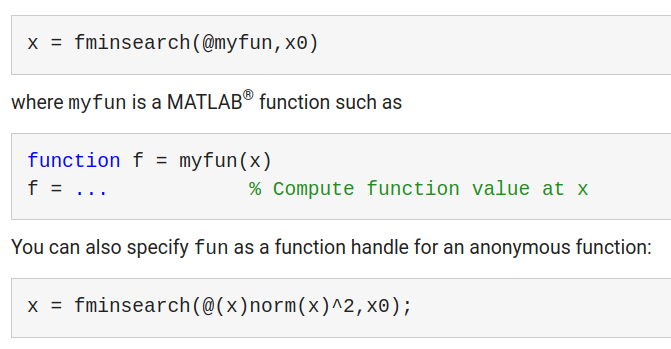

- `x0` is a vector for the initial design parameters

- `x` is the optimal solution, with the same size as `x0`

- The cost function, `myfun`, in this example, takes the design parameters as input and returns the cost as a scalar.  (This is the crux of these problems.)

### Example

**Implement the cost function, with the specified interface.**

$dist(C) = r_A + r_B = \sqrt{a^2 + C^2} + \sqrt{b^2 + (d-C)^2}$.

The only design/decision variable we have is the scalar value $C$.

function dist = cost_func(C)
    % Specific parameters - distances in km

C = 2.0000

min_dist = 7.0711

    a = 2;
    b = 3;
    d = 5;

d = 7.8310

    % Geometry

d = 7.3852

    rA = sqrt(a^2 + C.^2);

d = 8.3852

    rB = sqrt(b^2 + (d-C).^2);
    dist = rA + rB;
end
C0 = 1;
[C, min_dist] = fminsearch(@cost_func, C0)

**Test the cost function **

d = cost_func(0)
d = cost_func(3.5)
d = cost_func(5)

For C=2.0 km, the cost (path length) is 7.1 km


 Do the results make sense?

**Optimize: Find the "best" parameters**

% Initial conditions
x0 = 2.5;
[x_opt, fval_opt] = fminsearch(@cost_func, x0);
fprintf("For C=%.1f km, the cost (path length) is %.1f km\n", x_opt, fval_opt);

x_opt = 2.0000

x_opt = 2

x_opt = 2.0000

x_opt = 2

## Verify and Validate

How can we gain some confidence in our solution?

Is the solution sensitive to our choice of initial conditions?

xx0 = [0 2 4 5];
for ii = 1:length(xx0)

ans =    7.071067811865476


    x_opt = fminsearch(@cost_func, xx0(ii))

ans =    7.071126640079735


end

ans =    7.071126836500058


Does the solution get less optimal (the path get longer) if we use a slightly different design paramenter?

format long
cost_func(x_opt)
cost_func(x_opt*1.01)
cost_func(x_opt*0.99)

Visualize the cost in the local area of our solution. (This can quickly become difficult as the dimensions of the problem grow and the computational costs rise.)

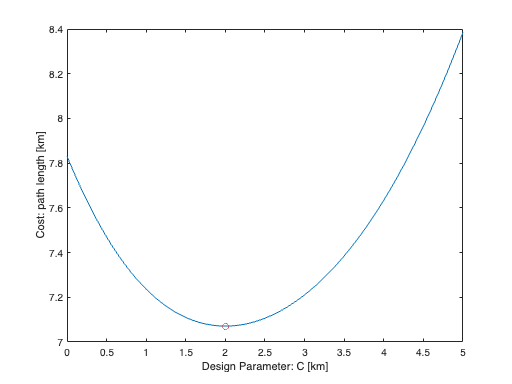

xx = linspace(0, 5, 100);
yy = cost_func(xx);
plot(xx,yy)

hold on
plot(x_opt, fval_opt, 'ro')
xlabel("Design Parameter: C [km]")
ylabel("Cost: path length [km]")